clc;
clear all;
close all;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code


#### Parameters

Parameters

Wireless packet type: SC


N_x = 8

N = 64

M_x = 15

zeta =     0.9850    0.9860    0.9870    0.9880    0.9890    0.9900


T_coh = 0.0038

N_packets_coh = 12

T = 144

SNR_dB = 36.5005

load SIM_training_CST_zeta_0_995_Nx_8_Mx_15
loss_CST_zeta_0_995_Nx_8_CST_Mx_15_L_13=loss_hist;

load SIM_training_CST_zeta_0_995_Nx_8_Mx_15_L_14
loss_CST_zeta_0_995_Nx_8_CST_Mx_15_L_14=loss_hist;

load SIM_training_CST_zeta_0_995_Nx_8_Mx_16_L_13
loss_CST_zeta_0_995_Nx_8_CST_Mx_16_L_13=loss_hist;

load SIM_training_CST_zeta_0_995_Nx_8_Mx_17_L_13
loss_CST_zeta_0_995_Nx_8_CST_Mx_17_L_13=loss_hist;

figure;
semilogy(loss_CST_zeta_0_995_Nx_8_CST_Mx_15_L_13,'LineWidth',2);  grid on; hold on 
semilogy(loss_CST_zeta_0_995_Nx_8_CST_Mx_15_L_14,'LineWidth',2);
semilogy(loss_CST_zeta_0_995_Nx_8_CST_Mx_16_L_13,'LineWidth',2);
semilogy(loss_CST_zeta_0_995_Nx_8_CST_Mx_17_L_13,'LineWidth',2);

xlabel('Iterations','Interpreter','latex');
ylabel('$\mathcal{L}=||\beta G-F||^2$','Interpreter','latex');
legend({'$M_x=15, L=13$','$M_x=15, L=14$','$M_x=16, L=13$','$M_x=17, L=13$','$\zeta=0.99$','$\zeta=0.988$'},'Interpreter','latex');

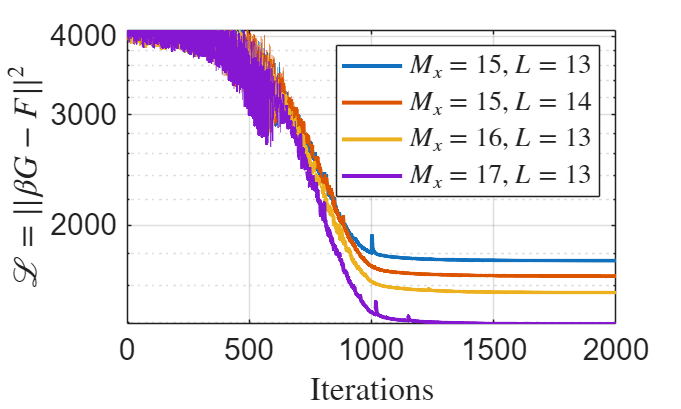

set(gca,'FontSize',font-5);



% load G_vs_eta_N_16_Zeta_0_8_to_1
% load G_vs_eta_N_16_Zeta_0_1_to_1_60_GHz
load SIM_training_noCST_single_zeta_28_GHz
loss_hist_G_vs_eta_N_16=loss_hist;

% load SIM_training_CST_single_zeta_28_GHz.mat
% loss_hist_G_vs_eta_N_16_CST=loss_hist;

load SIM_training_CST_zeta_sweep_28GHz.mat
loss_hist_G_vs_eta_N_16_CST=loss_hist_all;

load SIM_training_CST_zeta_0_988_Nx_8_Mx_15

Error using load
Unable to find file or directory 'SIM_training_CST_zeta_0_988_Nx_8_Mx_15'.

loss_CST_zeta_0_988_Nx_8_CST=loss_hist;

load SIM_training_CST_zeta_0_99_Nx_8_Mx_15
loss_CST_zeta_0_99_Nx_8_CST=loss_hist;

load SIM_training_CST_zeta_0_999_Nx_8_Mx_15
loss_CST_zeta_0_999_Nx_8_CST=loss_hist;

load SIM_training_CST_zeta_0_994_Nx_8_Mx_15
loss_CST_zeta_0_994_Nx_8_CST=loss_hist;



#### Evaluating the Loss function per iteration

figure;
semilogy(loss_CST_zeta_0_999_Nx_8_CST,'LineWidth',2);  grid on; hold on 
semilogy(loss_CST_zeta_0_995_Nx_8_CST,'LineWidth',2);
semilogy(loss_CST_zeta_0_994_Nx_8_CST,'LineWidth',2);
semilogy(loss_CST_zeta_0_99_Nx_8_CST,'LineWidth',2);
semilogy(loss_CST_zeta_0_988_Nx_8_CST,'LineWidth',2);
xlabel('Iterations','Interpreter','latex');
ylabel('$\mathcal{L}=||\beta G-F||^2$','Interpreter','latex');
legend({'$\zeta=0.999$','$\zeta=0.995$','$\zeta=0.994$','$\zeta=0.99$','$\zeta=0.988$'},'Interpreter','latex');
set(gca,'FontSize',font-5);

figure;
% semilogy(loss_hist{1},'LineWidth',2); grid on; hold on;
% semilogy(loss_hist{2},'LineWidth',2); grid on; hold on;
% semilogy(loss_hist{3},'LineWidth',2);
% semilogy(loss_hist{4},'LineWidth',2);
% semilogy(loss_hist{5},'LineWidth',2);
% semilogy(loss_hist_G_vs_eta_N_16,'LineWidth',2);hold on; grid on;
% semilogy(loss_hist_G_vs_eta_N_16{7},'LineWidth',2); 
% semilogy(loss_hist_G_vs_eta_N_16{8},'LineWidth',2);
% semilogy(loss_hist_G_vs_eta_N_16{9},'LineWidth',2);hold on; grid on;
% semilogy(loss_hist_G_vs_eta_N_16_CST{1},'LineWidth',2);hold on; grid on;
% semilogy(loss_hist_G_vs_eta_N_16_CST{2},'LineWidth',2);
% semilogy(loss_hist_G_vs_eta_N_16{10},'LineWidth',2);

semilogy(loss_hist_G_vs_eta_N_16_CST{1},'-.','LineWidth',2);hold on; grid on;
semilogy(loss_hist_G_vs_eta_N_16_CST{2},':','LineWidth',2);
semilogy(loss_hist_G_vs_eta_N_16_CST{3},'o-','LineWidth',2,'MarkerIndices',1:100:maxIter);
semilogy(loss_hist_G_vs_eta_N_16_CST{4},'LineWidth',2);
% semilogy(loss_hist_G_vs_eta_N_16_CST{6},'LineWidth',2);
%DFT results withouth CST
semilogy(loss_hist_G_vs_eta_N_16,'--','LineWidth',2);

xlabel('Iterations','Interpreter','latex');
ylabel('$\mathcal{L}=||\beta G-F||^2$','Interpreter','latex');
legend({strcat('$\zeta=',num2str(zeta(1)),'$'),...
    strcat('$\zeta=',num2str(zeta(2)),'$'),...
    strcat('$\zeta=',num2str(zeta(3)),'$'),...
    strcat('$\zeta=',num2str(zeta(4)),'$'),...
    strcat('$\zeta=',num2str(zeta_fixed),'$ (Ideal case)')},'Interpreter','latex')
set(gca,'FontSize',font);



%% ---- 1. Discover checkpoint directories ----
dataset_path = fullfile('..', 'Dataset');
ckpt_dirs = dir(fullfile(dataset_path, 'ablation_ckpt_zeta_*'));
ckpt_dirs = ckpt_dirs([ckpt_dirs.isdir]);   % keep directories only
 
if isempty(ckpt_dirs)
    error('No ablation_ckpt_zeta_* directories found in %s.\nRun the ablation script first.', dataset_path);
end
 
fprintf('Found %d zeta checkpoint director%s:\n', numel(ckpt_dirs), ...
    ternary(numel(ckpt_dirs)==1,'y','ies'));

Found 4 zeta checkpoint directories:


for d = 1:numel(ckpt_dirs)
    fprintf('  %s\n', ckpt_dirs(d).name);
end

  ablation_ckpt_zeta_0.986
  ablation_ckpt_zeta_0.987
  ablation_ckpt_zeta_0.988
  ablation_ckpt_zeta_0.989


 
%% ---- 2. Parse zeta value from directory name and load all combos ----
% Directory name format: ablation_ckpt_zeta_X.XXX
% Re-use whatever lambda the first checkpoint file reports (all should agree).
 
rows = {};   % will grow as we load; converted to table at the end
 
for d = 1:numel(ckpt_dirs)
    dir_name   = ckpt_dirs(d).name;
    zeta_str   = strrep(dir_name, 'ablation_ckpt_zeta_', '');
    zeta_val   = str2double(zeta_str);
    if isnan(zeta_val)
        warning('Could not parse zeta from directory name "%s" -- skipping.', dir_name);
        continue;
    end
 
    % combo_files = dir(fullfile(dir_name, 'combo_*.mat'));
    combo_files = dir(fullfile(dataset_path, dir_name, 'combo_*.mat'));
    if isempty(combo_files)
        fprintf('  %s: no completed combos yet, skipping.\n', dir_name);
        continue;
    end
    fprintf('  %s: %d completed combo(s) found.\n', dir_name, numel(combo_files));
 
    for f = 1:numel(combo_files)
        C = load(fullfile(combo_files(f).folder, combo_files(f).name));
        rows{end+1} = [C.T_SIM_cur, C.L_cur, C.M_cur, C.s_x_cur, ...
                       zeta_val, C.loss_final];  %#ok<SAGROW>
    end
end

  ablation_ckpt_zeta_0.986: 286 completed combo(s) found.
  ablation_ckpt_zeta_0.987: 272 completed combo(s) found.
  ablation_ckpt_zeta_0.988: 162 completed combo(s) found.
  ablation_ckpt_zeta_0.989: 181 completed combo(s) found.


 
if isempty(rows)
    error('No completed combos found across all checkpoint directories.');
end
 
%% ---- 3. Assemble table ----
mat = cell2mat(rows.');   % n_rows x 6
results_all = table(mat(:,1), mat(:,2), mat(:,3), mat(:,4), mat(:,5), mat(:,6), ...
    'VariableNames', {'T_SIM','L','M','s_x','zeta','loss_final'});
 
fprintf('\nTotal rows loaded: %d (across %d zeta value(s))\n', ...
    height(results_all), numel(unique(results_all.zeta)));


Total rows loaded: 901 (across 4 zeta value(s))


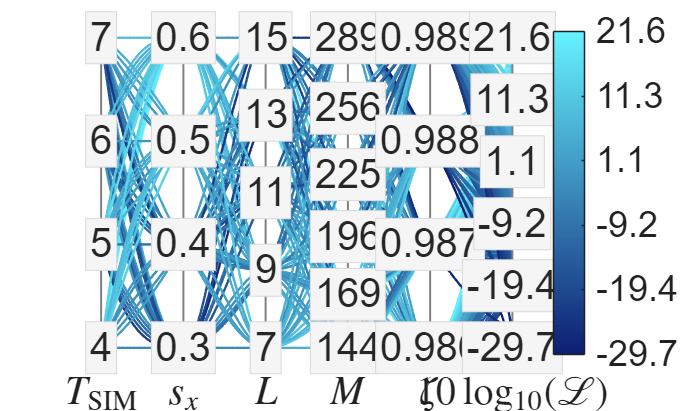

 
%% ---- 4. Build display table (normalise units) ----
results_disp           = results_all;
results_disp.T_SIM     = results_all.T_SIM / lambda;   % units of lambda
results_disp.s_x       = results_all.s_x   / lambda;   % units of lambda
 
%% ---- 5. Color mapping (loss-encoded, same blue gradient) ----
nColors          = 256;
dark_blue        = [0.05, 0.12, 0.45];
bright_light_blue = [0.40, 0.95, 1.00];
custom_blue_cmap = [linspace(dark_blue(1), bright_light_blue(1), nColors)', ...
                    linspace(dark_blue(2), bright_light_blue(2), nColors)', ...
                    linspace(dark_blue(3), bright_light_blue(3), nColors)'];
 
loss_min     = min(results_disp.loss_final);
loss_max     = max(results_disp.loss_final);
log_loss     = 10*log10(results_disp.loss_final);
log_loss_min = 10*log10(loss_min);
log_loss_max = 10*log10(loss_max);
% Color index on log scale so small-loss combos get well-separated colours
color_idx = round(1 + (nColors-1) * (log_loss - log_loss_min) / (log_loss_max - log_loss_min));
 
%% ---- 6. Build 6-column normalised matrix for parallel coordinates ----
% Column order: T_SIM/lam | L | M | s_x/lam | zeta | Loss
plot_matrix = [results_disp.T_SIM, results_disp.s_x, results_disp.L,...
               results_disp.M, results_disp.zeta, 10*log10(results_disp.loss_final)];
 
min_vals  = min(plot_matrix,  [], 1);
max_vals  = max(plot_matrix,  [], 1);
norm_mat  = (plot_matrix - min_vals) ./ (max_vals - min_vals);
 
n_axes    = 6;
x_orig    = 1:n_axes;
x_fine    = linspace(1, n_axes, 300);
 
%% ---- 7. Plot ----
figure; hold on;
 
% Background splines (one per combo)
for i = 1:size(norm_mat, 1)
    y_fine = pchip(x_orig, norm_mat(i,:), x_fine);
    plot(x_fine, y_fine, ...
        'Color', [custom_blue_cmap(color_idx(i),:), 0.35], ...
        'LineWidth', 1.2);
end
 
% Vertical axis lines
for x = 1:n_axes
    line([x x], [0 1], 'Color', [0.5 0.5 0.5], 'LineWidth', 1.0);
end
 
% Tick labels with background boxes
ticks_T    = unique(results_disp.T_SIM);
ticks_L    = unique(results_disp.L);
ticks_M    = unique(results_disp.M);
ticks_s    = unique(results_disp.s_x);
ticks_z    = unique(results_disp.zeta);
ticks_loss = 10.^(linspace(log10(loss_min), log10(loss_max), 6));   % original scale, evenly spaced in dB
tick_values_cell = {ticks_T, ticks_s, ticks_L, ticks_M, ticks_z, ticks_loss};
 
for x = 1:n_axes
    raw_ticks  = tick_values_cell{x};
    if x == n_axes   % loss axis: plot_matrix col is log10(loss), ticks are original scale
        norm_ticks = (10*log10(raw_ticks) - min_vals(x)) / (max_vals(x) - min_vals(x));
    else
        norm_ticks = (raw_ticks - min_vals(x)) / (max_vals(x) - min_vals(x));
    end
    for t = 1:numel(norm_ticks)
        if x == n_axes
            db_val = 10*log10(raw_ticks(t));
            label_str  = sprintf('%.1f', db_val);
            tick_interp = 'none';
        else
            label_str  = num2str(raw_ticks(t), '%.3g');
            tick_interp = 'none';
        end
        text(x, norm_ticks(t), label_str, ...
            'FontSize', font, ...
            'Color', [0.15 0.15 0.15], ...
            'BackgroundColor', [0.96 0.96 0.96], ...
            'EdgeColor',  [0.85 0.85 0.85], ...
            'Margin', 2, ...
            'Interpreter',         tick_interp, ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment',   'middle');
    end
end
 
% X-axis labels (LaTeX)
latex_labels = {'$$\frac{T_\mathrm{SIM}}{\lambda}$$', '$$\frac{s_x}{\lambda}$$',...
                '$$L$$', '$$M$$', '$$\zeta$$', '$$10\log_{10}(\mathcal{L})$$'};
for x = 1:n_axes
    text(x, -0.06, latex_labels{x}, ...
        'Interpreter',       'latex', ...
        'FontSize',          font, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment', 'top');
end
 
hold off;
 
xlim([0.7, n_axes + 0.3]);
ylim([-0.02, 1.02]);
set(gca, 'Box',    'off', ...
         'XColor', 'none', ...
         'YColor', 'none', ...
         'FontSize', font);
 
colormap(custom_blue_cmap);
c = colorbar;
clim([log_loss_min, log_loss_max]);
cb_log_ticks = linspace(log_loss_min, log_loss_max, 6);
c.Ticks      = cb_log_ticks;
c.TickLabels = arrayfun(@(v) sprintf('%.1f', v), cb_log_ticks, 'UniformOutput', false);

#### ANOVA


%% ===================== 4. Sensitivity ranking via N-way ANOVA =====================
if license('test', 'Statistics_Toolbox')
    [p, tbl, stats] = anovan(results_disp.loss_final, ...
        {results_disp.T_SIM, results_disp.L, results_disp.M, results_disp.s_x}, ...
        'model',    'interaction', ...
        'varnames', {'T_SIM','L','M','s_x'}, ...
        'display',  'off');

    % ---- Extract rows from tbl (skip header row 1, Error and Total at end) ----
    % tbl columns: {Source, SS, df, Singular?, MS, F, p}
    n_rows   = size(tbl, 1);
    term_rows = 2 : n_rows-2;   % excludes header, Error, Total

    sources  = tbl(term_rows, 1);
    SS_vals  = cell2mat(tbl(term_rows, 2));
    df_vals  = cell2mat(tbl(term_rows, 3));
    F_vals   = cell2mat(tbl(term_rows, 6));
    p_vals   = cell2mat(tbl(term_rows, 7));

    % ---- SS for Total (last row) ----
    SS_total = cell2mat(tbl(end, 2));

    % ---- eta-squared: proportion of total variance explained ----
    eta2 = SS_vals / SS_total * 100;   % in percent

    % ---- Sort by SS descending ----
    [SS_sorted, sort_idx] = sort(SS_vals, 'descend');
    sources_sorted = sources(sort_idx);
    df_sorted      = df_vals(sort_idx);
    F_sorted       = F_vals(sort_idx);
    p_sorted       = p_vals(sort_idx);
    eta2_sorted    = eta2(sort_idx);

    % ---- Print ranked table ----
    fprintf('\n%-15s  %8s  %10s  %4s  %10s  %12s\n', ...
        'Source', 'eta^2 (%)', 'SS', 'df', 'F', 'p-value');
    fprintf('%s\n', repmat('-', 1, 70));
    for k = 1:numel(sort_idx)
        sig = '';
        if p_sorted(k) < 0.001,  sig = '***';
        elseif p_sorted(k) < 0.01,  sig = '**';
        elseif p_sorted(k) < 0.05,  sig = '*';
        else,                        sig = 'n.s.';
        end
        fprintf('%-15s  %7.2f%%  %10.2f  %4d  %10.4f  %12.4e  %s\n', ...
            sources_sorted{k}, eta2_sorted(k), SS_sorted(k), df_sorted(k), ...
            F_sorted(k), p_sorted(k), sig);
    end
    fprintf('%s\n', repmat('-', 1, 70));
    fprintf('%-15s  %10.2f  %4d\n', 'Total', SS_total, cell2mat(tbl(end,3)));
    fprintf('\nSignificance codes: *** p<0.001  ** p<0.01  * p<0.05  n.s. p>=0.05\n');
    fprintf('eta^2 = SS_term / SS_total (effect size, higher = more influential)\n');

    % ---- Save ranked results as a workspace table for downstream use ----
    anova_ranked = table( ...
        sources_sorted,  ...
        SS_sorted,       ...
        df_sorted,       ...
        F_sorted,        ...
        p_sorted,        ...
        eta2_sorted,     ...
        'VariableNames', {'Source','SS','df','F','p_value','eta2_pct'});
    % eta2_pct: eta^2 expressed as percentage of SS_total
    fprintf('\nResults saved in workspace variable: anova_ranked\n');

else
    warning('Statistics and Machine Learning Toolbox not found -- skipping ANOVA.');
end


Source           eta^2 (%)          SS    df           F       p-value


----------------------------------------------------------------------


T_SIM:s_x          27.96%    25513.74     9    112.4773   9.5284e-120  ***
T_SIM              12.50%    11409.96     3    150.9024    8.6074e-72  ***
L:s_x              11.15%    10171.04    12     33.6293    1.6129e-58  ***
L                   3.66%     3341.41     4     33.1438    7.6116e-25  ***
T_SIM:L             1.73%     1576.42    12      5.2122    2.4187e-08  ***
M:s_x               1.15%     1049.89    14      2.9754    2.0457e-04  ***
M                   0.35%      317.65     4      3.1508    1.4078e-02  *
s_x                 0.27%      243.94     2      4.8394    8.2436e-03  **
L:M                 0.24%      218.75    20      0.4340    9.8563e-01  n.s.
T_SIM:M             0.22%      202.73    15      0.5362    9.2059e-01  n.s.


----------------------------------------------------------------------


Total              91243.77   661



Significance codes: *** p<0.001  ** p<0.01  * p<0.05  n.s. p>=0.05


eta^2 = SS_term / SS_total (effect size, higher = more influential)



Results saved in workspace variable: anova_ranked



%% ---- 1b. Ground-truth check: don't trust colors, read the actual rows ----
% Most reliable answer to "which direction should each parameter move":
% just sort by loss_final and look at the extremes directly.
sorted_results = sortrows(results_disp, 'loss_final');
fprintf('\n--- 10 BEST combos (lowest loss) ---\n');


--- 10 BEST combos (lowest loss) ---


disp(sorted_results(1:10, {'T_SIM','s_x','L','M','loss_final'}));

    T_SIM    s_x    L      M     loss_final
    _____    ___    __    ___    __________

      7      0.3    15    289    0.0014666 
      7      0.3    15    256     0.005632 
      6      0.4    13    196    0.0060005 
      7      0.4    15    289     0.009202 
      7      0.4    15    289     0.010833 
      7      0.3    15    225     0.011395 
      7      0.3    13    289     0.012046 
      7      0.4    11    225     0.012224 
      7      0.4    15    144     0.012828 
      7      0.4    15    256     0.013185 



fprintf('\n--- 10 WORST combos (highest loss) ---\n');


--- 10 WORST combos (highest loss) ---


disp(sorted_results(end-9:end, {'T_SIM','s_x','L','M','loss_final'}));

    T_SIM    s_x    L      M     loss_final
    _____    ___    __    ___    __________

      4      0.6     9    225      39.125  
      5      0.6    15    144      46.726  
      4      0.6    11    196      51.264  
      5      0.6    15    196      53.752  
      5      0.6    15    169      53.964  
      4      0.6    11    144       75.37  
      4      0.6    13    169      104.53  
      4      0.6    13    196      114.95  
      4      0.6    15    144      137.92  
      4      0.6    15    169      144.08  




%% ---- 1b. Ground-truth check: don't trust colors, read the actual rows ----
% Most reliable answer to "which direction should each parameter move":
% just sort by loss_final and look at the extremes directly.
sorted_results = sortrows(results_disp, 'loss_final');
fprintf('\n--- 10 BEST combos (lowest loss) ---\n');


--- 10 BEST combos (lowest loss) ---


disp(sorted_results(1:10, {'T_SIM','s_x','L','M','loss_final'}));

    T_SIM    s_x    L      M     loss_final
    _____    ___    __    ___    __________

      7      0.3    15    289    0.0014666 
      7      0.3    15    256     0.005632 
      6      0.4    13    196    0.0060005 
      7      0.4    15    289     0.009202 
      7      0.4    15    289     0.010833 
      7      0.3    15    225     0.011395 
      7      0.3    13    289     0.012046 
      7      0.4    11    225     0.012224 
      7      0.4    15    144     0.012828 
      7      0.4    15    256     0.013185 



fprintf('\n--- 10 WORST combos (highest loss) ---\n');


--- 10 WORST combos (highest loss) ---


disp(sorted_results(end-9:end, {'T_SIM','s_x','L','M','loss_final'}));

    T_SIM    s_x    L      M     loss_final
    _____    ___    __    ___    __________

      4      0.6     9    225      39.125  
      5      0.6    15    144      46.726  
      4      0.6    11    196      51.264  
      5      0.6    15    196      53.752  
      5      0.6    15    169      53.964  
      4      0.6    11    144       75.37  
      4      0.6    13    169      104.53  
      4      0.6    13    196      114.95  
      4      0.6    15    144      137.92  
      4      0.6    15    169      144.08  




--- 10 BEST combos (lowest loss) ---


% %% ---- 1c. Decluttered parallel plot: only the two extreme quintiles ----
% % 81 lines across 5 overlapping colors is hard to read reliably by eye.
% % Showing only Q1 (best) vs Q5 (worst) -- roughly 32 lines, 2 colors --
% % makes "where do the best lines sit on each axis" much easier to see,
% % and sidesteps the legend-ordering ambiguity above since there are only
% % two groups to keep straight.
% extremes = results_disp(results_disp.loss_bin=='Q1' | results_disp.loss_bin=='Q5', :);
% extremes.loss_bin = removecats(extremes.loss_bin);
% 
% cmap_extremes = cmap([1 nBins], :);   % reuse the same parula(nBins) defined above, just the two ends
% 
% figure;
% parallelplot(extremes, 'CoordinateVariables', ...
%     {'T_SIM_over_lambda','L','M','s_x_over_lambda','loss_final'}, ...
%     'GroupVariable', 'loss_bin', 'Color', cmap_extremes);
% title('Best (Q1) vs. worst (Q5) combos only -- decluttered view');


--- 10 BEST combos (lowest loss) ---


    T_SIM    L      M     s_x    loss_final
    _____    __    ___    ___    __________

      7      15    289    0.3    0.0014666 
      7      15    256    0.3     0.005632 
      6      13    196    0.4    0.0060005 
      7      15    289    0.4     0.009202 
      7      15    289    0.4     0.010833 
      7      15    225    0.3     0.011395 
      7      13    289    0.3     0.012046 
      7      11    225    0.4     0.012224 
      7      15    144    0.4     0.012828 
      7      15    256    0.4     0.013185 




--- 10 WORST combos (highest loss) ---


    T_SIM    L      M     s_x    loss_final
    _____    __    ___    ___    __________

      4       9    225    0.6      39.125  
      5      15    144    0.6      46.726  
      4      11    196    0.6      51.264  
      5      15    196    0.6      53.752  
      5      15    169    0.6      53.964  
      4      11    144    0.6       75.37  
      4      13    169    0.6      104.53  
      4      13    196    0.6      114.95  
      4      15    144    0.6      137.92  
      4      15    169    0.6      144.08  



% 
% %% ---- 1c. Decluttered parallel plot: only the two extreme quintiles ----
% % 81 lines across 5 overlapping colors is hard to read reliably by eye.
% % Showing only Q1 (best) vs Q5 (worst) -- roughly 32 lines, 2 colors --
% % makes "where do the best lines sit on each axis" much easier to see,
% % and sidesteps the legend-ordering ambiguity above since there are only
% % two groups to keep straight.
% extremes = results_disp(results_disp.loss_final=='Q1' | results_disp.loss_final=='Q5', :);
% extremes.loss_final = removecats(extremes.loss_final);
% 
% cmap_extremes = cmap([1 nBins], :);   % reuse the same parula(nBins) defined above, just the two ends
% 
% figure;
% parallelplot(extremes, 'CoordinateVariables', ...
%     {'T_SIM_over_lambda','L','M','s_x_over_lambda','loss_final'}, ...
%     'GroupVariable', 'loss_bin', 'Color', cmap_extremes);
% title('Best (Q1) vs. worst (Q5) combos only -- decluttered view');



--- ANOVA: contribution to loss_final variance ---


    {'Source'   }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'T_SIM'    }    {[2.5804e+03]}    {[   3]}    {[        0]}    {[860.1452]}    {[127.2769]}    {[9.3235e-59]}
    {'L'        }    {[  851.5160]}    {[   2]}    {[        1]}    {[425.7580]}    {[ 63.0000]}    {[1.1257e-24]}
    {'M'        }    {[    0.1451]}    {[   1]}    {[        1]}    {[  0.1451]}    {[  0.0215]}    {[    0.8836]}
    {'s_x'      }    {[    3.5597]}    {[   1]}    {[        1]}    {[  3.5597]}    {[  0.5267]}    {[    0.4684]}
    {'T_SIM:L'  }    {[  180.4878]}    {[  12]}    {[        0]}    {[ 15.0407]}    {[  2.2256]}    {[    0.0101]}
    {'T_SIM:M'  }    {[   37.1787]}    {[  15]}    {[        0]}    {[  2.4786]}    {[  0.3668]}    {[    0.9864]}
    {'T_SIM:s_x'}    {[5.3873e+03]}    {[   9]}    {[        0]}    {[598.5928]}    {[ 88.5746]}    {[1.3764e-91]}
    {'L:M'      }    {[   58.6667]}    {[  19]}    {[        1]}    {[  3.0877]}

p-values (main effects): T_SIM=0.0000, L=0.0000, M=0.8836, s_x=0.4684


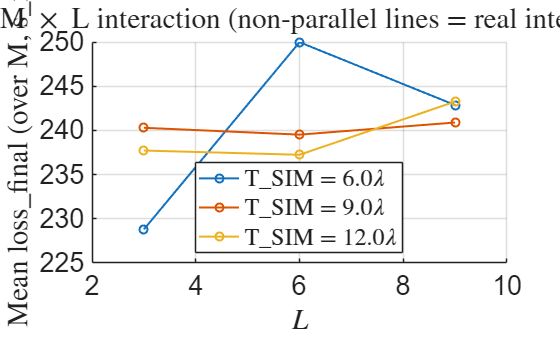

%% ===================== 5. T_SIM x L interaction plot =====================
% ANOVA found T_SIM:L significant (p=0.026) and larger than L's own main
% effect (p=0.047) -- meaning L's effect on loss isn't a single direction,
% it depends on T_SIM. This plots mean loss_final for each (T_SIM, L) cell,
% averaged over M and s_x. Non-parallel/crossing lines = real interaction
% (as opposed to T_SIM:M, T_SIM:s_x, L:M, L:s_x, M:s_x, none of which were
% significant, so those pairs would look closer to parallel if plotted).
[uT, ~, iT] = unique(results.T_SIM);
[uL, ~, iL] = unique(results.L);
meanGrid = accumarray([iT iL], results.loss_final, [], @mean);   % nT x nL
 
figure; hold on; grid on;
colors = lines(numel(uT));
for i = 1:numel(uT)
    plot(uL, meanGrid(i,:), '-o', 'LineWidth', 1.5, 'Color', colors(i,:), ...
        'DisplayName', sprintf('T\\_SIM = %.1f$\\lambda$', uT(i)/lambda));
end
set(gca, 'FontSize', font);
xlabel('$L$', 'Interpreter','latex');
ylabel('Mean loss\_final (over M, s\_x)', 'Interpreter','latex');
legend('Interpreter','latex', 'Location','best');
title('T\_SIM $\times$ L interaction (non-parallel lines = real interaction)', 'Interpreter','latex');

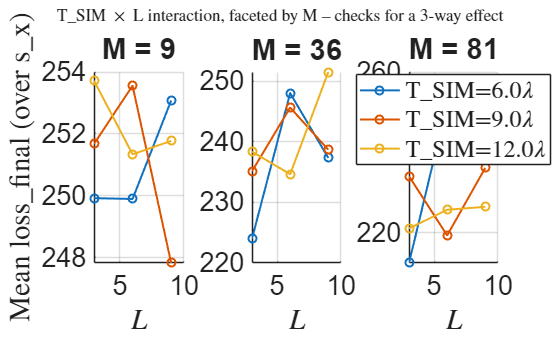

%% ===================== 6. T_SIM x L interaction, faceted by M =====================
% The plot above averages over M too (9 raw combos per point), and M
% explains 36% of total variance -- far more than T_SIM, L, or their
% interaction. That averaging could be manufacturing or masking the
% apparent T_SIM:L pattern. Faceting by M isolates it: if the spike shows
% up at every M level, it's a real 2-way effect; if it only appears at one
% M (most likely M=9, the most resource-starved case), that's evidence of
% an unmodeled 3-way T_SIM:L:M interaction the 'interaction'-only ANOVA
% model can't capture -- and a likely contributor to the 32.8% Error term.
uM = unique(results.M);
figure;
for j = 1:numel(uM)
    subplot(1, numel(uM), j); hold on; grid on;
    sub = results(results.M==uM(j), :);
    [uT2, ~, iT2] = unique(sub.T_SIM);
    [uL2, ~, iL2] = unique(sub.L);
    meanGrid2 = accumarray([iT2 iL2], sub.loss_final, [], @mean);
 
    colors = lines(numel(uT2));
    for i = 1:numel(uT2)
        plot(uL2, meanGrid2(i,:), '-o', 'LineWidth', 1.5, 'Color', colors(i,:), ...
            'DisplayName', sprintf('T\\_SIM=%.1f$\\lambda$', uT2(i)/lambda));
    end
    xlabel('$L$', 'Interpreter','latex');
    if j == 1
        ylabel('Mean loss\_final (over s\_x)', 'Interpreter','latex');
    end
    title(sprintf('M = %d', uM(j)));
    if j == numel(uM)
        legend('Interpreter','latex', 'Location','best');
    end
    set(gca, 'FontSize', font);
end
sgtitle('T\_SIM $\times$ L interaction, faceted by M -- checks for a 3-way effect', 'Interpreter','latex');

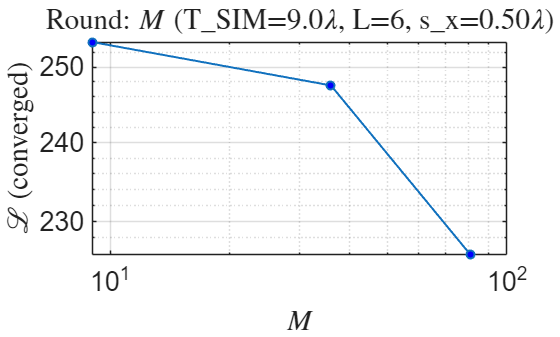


% --- Round: M ---
mask = results.T_SIM==T_SIM_base & results.L==L_base & results.s_x==s_x_base;
sub = sortrows(results(mask,:), 'M');
figure;
semilogy(sub.M, sub.loss_final, '-o', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on; set(gca,'XScale','log','FontSize',font);
xlabel('$M$','Interpreter','latex'); ylabel('$\mathcal{L}$ (converged)','Interpreter','latex');
title(sprintf('Round: $M$ (T\\_SIM=%.1f$\\lambda$, L=%d, s\\_x=%.2f$\\lambda$)', ...
    T_SIM_base/lambda, L_base, s_x_base/lambda), 'Interpreter','latex');

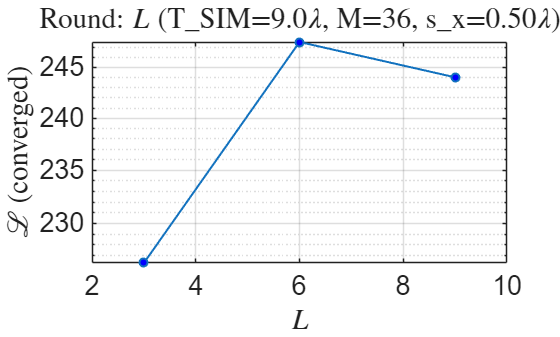


% --- Round: L ---
mask = results.T_SIM==T_SIM_base & results.M==M_base & results.s_x==s_x_base;
sub = sortrows(results(mask,:), 'L');
figure;
semilogy(sub.L, sub.loss_final, '-o', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on; set(gca,'FontSize',font);
xlabel('$L$','Interpreter','latex'); ylabel('$\mathcal{L}$ (converged)','Interpreter','latex');
title(sprintf('Round: $L$ (T\\_SIM=%.1f$\\lambda$, M=%d, s\\_x=%.2f$\\lambda$)', ...
    T_SIM_base/lambda, M_base, s_x_base/lambda), 'Interpreter','latex');

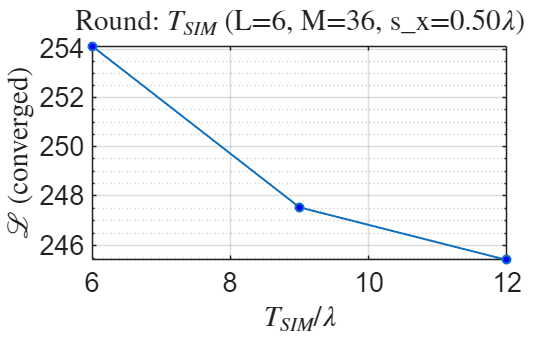


% --- Round: T_SIM ---
mask = results.L==L_base & results.M==M_base & results.s_x==s_x_base;
sub = sortrows(results(mask,:), 'T_SIM');
figure;
semilogy(sub.T_SIM/lambda, sub.loss_final, '-o', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on; set(gca,'FontSize',font);
xlabel('$T_{SIM}/\lambda$','Interpreter','latex'); ylabel('$\mathcal{L}$ (converged)','Interpreter','latex');
title(sprintf('Round: $T_{SIM}$ (L=%d, M=%d, s\\_x=%.2f$\\lambda$)', ...
    L_base, M_base, s_x_base/lambda), 'Interpreter','latex');

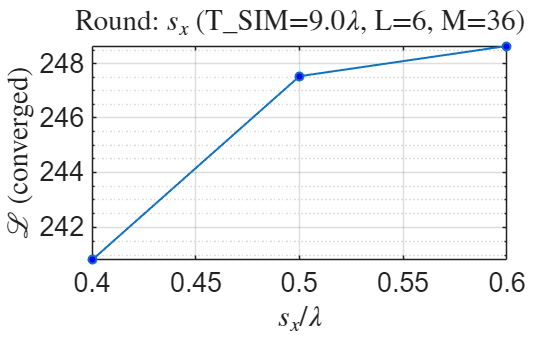


% --- Round: s_x ---
mask = results.T_SIM==T_SIM_base & results.L==L_base & results.M==M_base;
sub = sortrows(results(mask,:), 's_x');
figure;
semilogy(sub.s_x/lambda, sub.loss_final, '-o', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on; set(gca,'FontSize',font);
xlabel('$s_x/\lambda$','Interpreter','latex'); ylabel('$\mathcal{L}$ (converged)','Interpreter','latex');
title(sprintf('Round: $s_x$ (T\\_SIM=%.1f$\\lambda$, L=%d, M=%d)', ...
    T_SIM_base/lambda, L_base, M_base), 'Interpreter','latex');

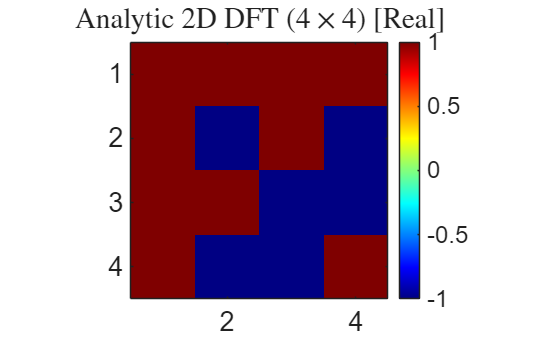




% Evaluating target 2D-DFT matrix F in Eq. (8) as
F = dft2_matrix(N_x, N_y);   % N_xN_y x N_xN_y, matches paper definition. [Eq. (11), 1]

figure
% subplot 121
imagesc(real(F))
axis image
colormap jet
colorbar
title('Analytic {2D DFT} ($4\times  4$) [Real]','Interpreter','latex');
set(gca,'FontSize',font);

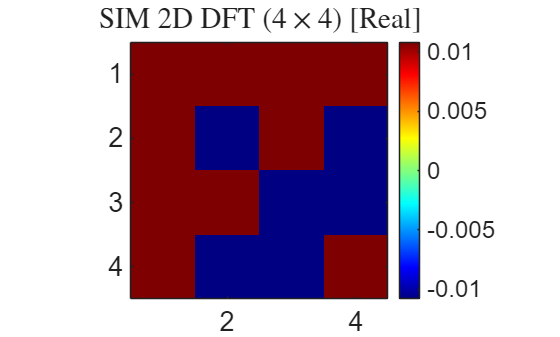


figure;
% subplot 122
G=G_vs_eta{9};
imagesc(-real(G))
axis image
colormap jet
colorbar
title('SIM {2D DFT} ($4\times  4$) [Real]','Interpreter','latex');
set(gca,'FontSize',font);

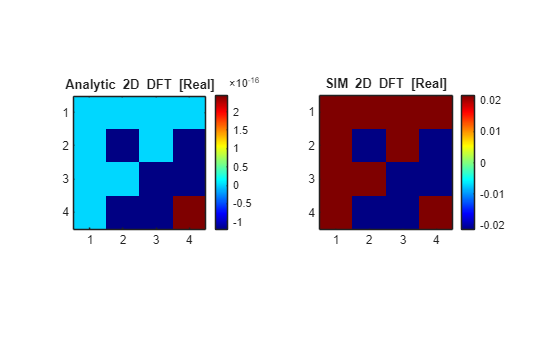


figure
subplot 121
imagesc(imag(F))
axis image
colormap jet
colorbar
title('Analytic {2D DFT} [Real]')

subplot 122
G=G_vs_eta{9};
imagesc(-imag(G))
axis image
colormap jet
colorbar
title('{SIM 2D DFT} [Real]')

function F = dft2_matrix(Nx, Ny)
% Matches eq. (11): F(n,nhat) = exp(-j2pi (nx-1)(nhx-1)/Nx) * exp(-j2pi (ny-1)(nhy-1)/Ny)
    N = Nx*Ny;
    F = zeros(N,N);
    for n = 1:N
        [nx, ny] = ind2sub([Nx, Ny], n); % careful: Matlab ind2sub uses column-major; we want nx fastest
        % We'll define our own mapping: nx = mod(n-1,Nx)+1, ny = floor((n-1)/Nx)+1
        nx = mod(n-1, Nx) + 1;
        ny = floor((n-1)/Nx) + 1;
        for nh = 1:N
            nhx = mod(nh-1, Nx) + 1;
            nhy = floor((nh-1)/Nx) + 1;
            F(n,nh) = exp(-1j*2*pi*(nx-1)*(nhx-1)/Nx) * exp(-1j*2*pi*(ny-1)*(nhy-1)/Ny);
        end
    end
end

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function Lval = loss_from_xi(xi, WL, W, W0, F)

    % Forward model
    [G, ~] = forward_G(WL, W, W0, xi);

    % Optimal beta (Eq. 21)
    g = G(:);
    f = F(:);
    beta = (g' * f) / (g' * g);

    % Loss (Eq. 12)
    E = beta*G - F;
    Lval = norm(E,'fro')^2;
end

function [G, Gamma] = forward_G(WL, W, W0, xi)
    % This function evaluates all the products of Gamma_l*W_l as follows from Eq. (2)
    % Construct Gamma matrices and forward multiply to get G.
    L = numel(xi);
    Gamma = cell(L,1);
    
    %Evaluates the Gamma matrix per layer as follows from Eq. (3)
    for l = 1:L
        Gamma{l} = diag(exp(1j*xi{l}));
    end
    
    %Evaluates the multiplication Gamma_l*W_l
    X = W0;
    for l = 1:(L-1)
        X = W{l} * Gamma{l} * X;
    end
    X = Gamma{L} * X;
    G = WL * X;
    
    
end

function out = ternary(cond, a, b)
    if cond, out = a; else, out = b; end
end